load iris.mat

model = { Xtrain , Ytrain , 'c', [], [],'RBF_kernel'};

algorithm = 'gridsearch';


[gam ,sig2 , cost ] = tunelssvm(model, algorithm, 'crossvalidatelssvm',{10, 'misclass'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.9512
                                          [sig2]        0.11221
                                          F(X)=         0.04
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.047357   0.0092104
    cost of starting values:           0.33
    time needed for 1 evaluation (sec):0
    limits of the grid:   [gam]         0.04735736      141.1703
                          [sig2]        0.0092104      1.3669
 
OPTIMIZATION IN LOG SCALE...


grain = 7

FIRST ITERATION:
   X=-3.05     -1.3541 ,F(X)=0.04;
ITERATION: 2
  dF=0.02, dX=0.53199, X=-3.3273    -0.90007 ,F(X)=0.02;
Obtained hyper-parameters: [gamma sig2]: 0.035889     0.40654


disp(gam);

    0.0359



disp(sig2);

    0.4065



disp(cost);

    0.0200



[alpha, b] = trainlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'RBF_kernel'});

[Yest, Ylatent] = simlssvm({ Xtrain , Ytrain , 'c', gam, sig2,'RBF_kernel'},{alpha, b},Xtest);

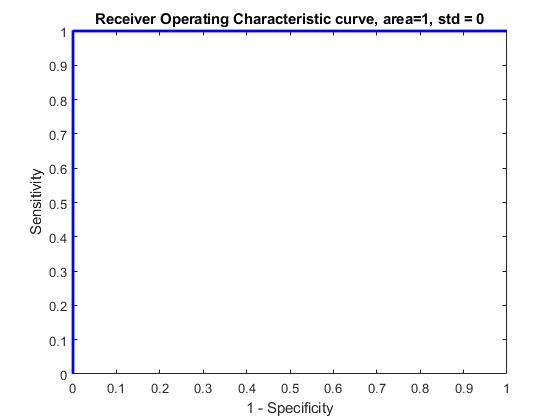

roc(Ylatent, Ytest);

gam = 1;

sig2 = 0.05;

bay_modoutClass({ Xtrain , Ytrain , 'c', gam, sig2,'RBF_kernel'},'figure');

 COMPUTING PLOT OF MODERATED OUTPUT


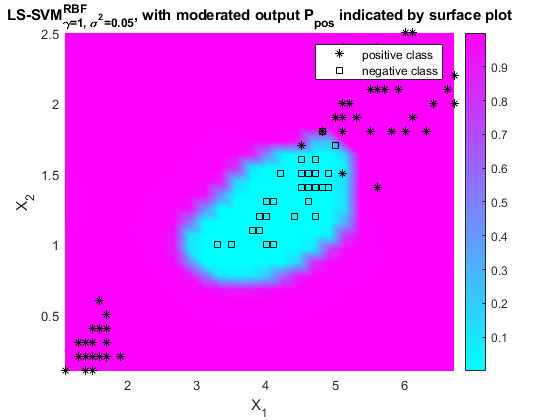

colorbar